# Método de Euler

En este script vamos a estudiar e implementar el método de Euler para resolver ecuaciones diferenciales ordinarias.

Supongamos que tenemos la siguiente ecuación diferencial:

    $X' = f(t, X)$,

    $X(t_0) = X_0$,

donde $X : \mathbb{R} \rightarrow \mathbb{R}^n$, $f : \mathbb{R}^{n+1} \rightarrow \mathbb{R}^n$, $t_0 \in \mathbb{R}$ y $X_0 \in \mathbb{R}^n$.

Podemos expresar la función $X$ en un entorno de $t_0$ mediante su desarrollo de Taylor como

    
$$\begin{array}{rcl}
X(t_0 + h) & = &
X(t_0) + h X'(t_0) + \mathcal{O}(h^2) \\
& = & X_0 + h f(t_0, X_0) + \mathcal{O}(h^2).
\end{array}$$


Así, dado un paso $h > 0$ podemos calcular $X_1 = X(t_1)$, donde $t_1 = t_0 + h$ y podemos volver a aplicar Taylor: $X(t_1 + h) = X_1 + h f(t_1, X_1) + \mathcal{O}(h^2)$.

Sean $t_i = t_0 + h * i$ y $X_i = X(t_i)$. Entonces, iterando este método, obtenemos

    $X_{i+1} = X_i + hf(t_i, X_i) + \mathcal{O}(h^2)$,

e ignorando el término cuadrático (del que dependerá el error), tenemos el método de Euler.

Podemos definir un máximo $N
$ de iteraciones y aplicar este método. Obtendremos entonces una matriz $(N + 1) \times n$, en la que cada fila es un punto (aproximado) por el que pasa la función $X$ en un tiempo $t_i$ determinado. Para obtener $X(t)$ para un $t \in [t_0, t_N]$ cualquiera podemos proceder por combinación convexa de los $t_i, t_{i+1} : t \in [t_i, t_{i+1}]$.

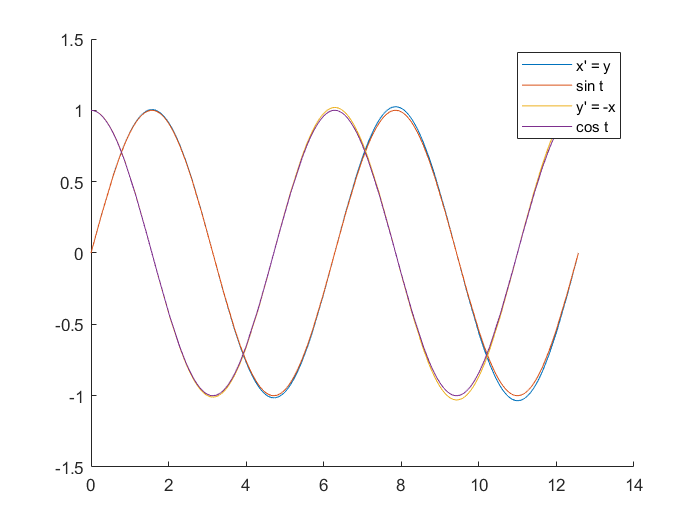

f = @(t, X) [X(2), -X(1)];

t0 = 0;
tn = 4 * pi;

[F, G] = euler(f, t0, [0 1], tn, 2000);

figure
hold on
fplot(F, [t0 tn]);
fplot(@(t) sin(t), [t0, tn]);
fplot(G, [t0 tn]);
fplot(@(t) cos(t), [t0, tn]);
legend(["x' = y", "sin t", "y' = -x", "cos t"]);
hold off

function varargout = euler(f, t0, X0, tn, n)
    % f : IR x IR^n -> IR^n
    if nargout ~= length(X0)
        error('se esperaba devolver %d funciones, pero había %d', ...
              length(X0), nargout)
    end
    h = (tn - t0) / n;
    Xs = zeros(n + 1, length(X0));
    Xs(1, :) = X0;
    for i = 1:n
        Xs(i + 1, :) = Xs(i, :) + h * f(t0 + (i-1) * h, Xs(i, :));
    end
    varargout = cell(1, nargout);
    for i = 1:nargout
        varargout{i} = @(t) approximation(Xs(:, i), t, t0, tn, n);
    end
end

function X = approximation(Xs, t, t0, tn, n)
    lambda = (t - t0)./ (tn - t0);
    pseudoIndex = lambda * (n + 1) + (1 - lambda);
    index1 = floor(pseudoIndex);
    index2 = ceil(pseudoIndex);
    mu = pseudoIndex - index1;
    X = (1 - mu).* Xs(index1) + mu.* Xs(index2);
end